# HW 3

clear; clc; close;

## Problem 1

% part B
s = tf('s');
G = 1.2/(s+1.2)

G =
 
    1.2
  -------
  s + 1.2
 
Continuous-time transfer function.



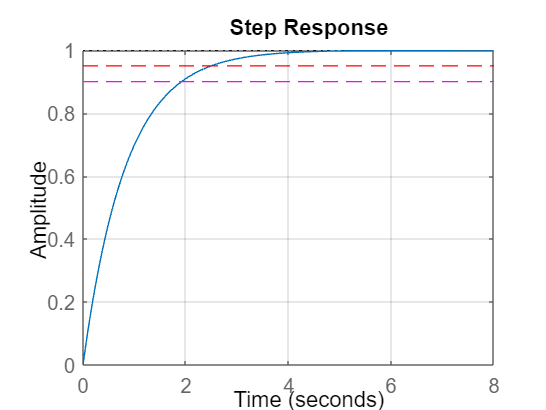

figure; step(G);
hold on;
guessSS = 1;
time = [0:8];
percent90 = repelem(guessSS*.9,length(time));
plot(time,percent90,'--m')
percent95 = repelem(guessSS*.95,length(time));
plot(time,percent95,'--r')
grid on;

## Problem 2

clear; clc; close;
s = tf('s');
G = 4/(s^2+.8*s+4)

G =
 
         4
  ---------------
  s^2 + 0.8 s + 4
 
Continuous-time transfer function.



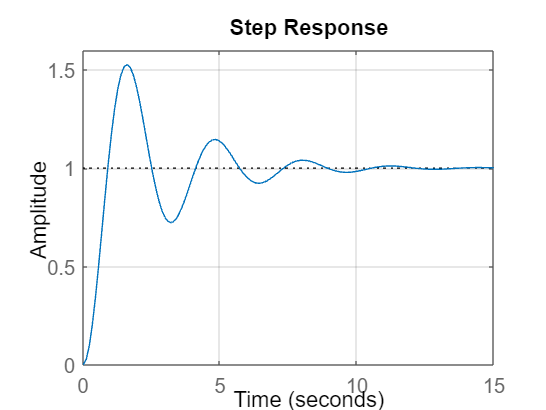

figure; step(G);
grid on;

## Problem 3

clear; clc; close;
s = tf('s');
G = 4/(s^2+1.4*s+4)

G =
 
         4
  ---------------
  s^2 + 1.4 s + 4
 
Continuous-time transfer function.



figure; step(G);
grid on;

## Problem 4

clear; clc; close;
s = tf('s');
G = 3*(s+3)/((s+.2)*(4*s+1))

G =
 
        3 s + 9
  -------------------
  4 s^2 + 1.8 s + 0.2
 
Continuous-time transfer function.



figure; step(G);
grid on;

## Problem 5

clear; clc; close;
s = tf('s');
G = .8304/(s^2+.1172*s+.8304)

G =
 
          0.8304
  -----------------------
  s^2 + 0.1172 s + 0.8304
 
Continuous-time transfer function.



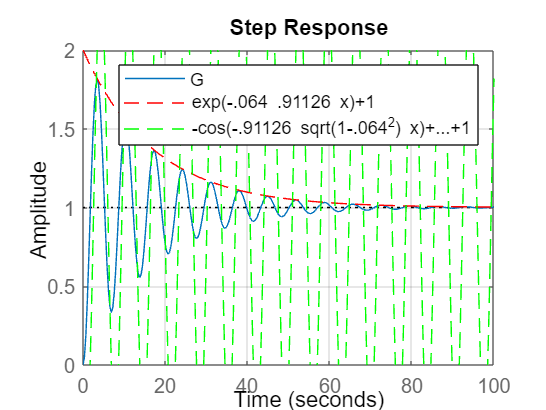

figure; step(G);
grid on;
hold on;
fplot(@(x) exp(-.064*.91126*x)+1, '--r') % e^ dampingRatio * natural frequency
fplot(@(x) -cos(-.91126*sqrt(1-.064^2)*x) +sin(-.91126*sqrt(1-.064^2)*x)  +1, '--g')
legend()